## Protein Folding with Genetic Algorithms

Template by Ahmet Sacan

Author(s): **[[WRITE YOUR NAME HERE]]**

This Notebook is filled in with the expected outputs. You do not need to change anything in this notebook. Write the functions as instructed in the following sections as separate files. When you are done, run this Notebook to regenerate the outputs and figures using your functions.

**Warning:** This assignment is an oversimplification of the forces and interactions involved in protein folding. Model protein folding as a minimization problem. While a state of the art implementation would use a more complete force-field (where bonded and non-bonded interactions) are implemented, we use here possibly inaccurate simplifications to calculate the fitness a folded protein.

In this assignment, you are going to "fold" a protein using Genetic Algorithms. The genetic algorithm will be used to find the coordinates of amino acids that result in the best "fitness".

### Changes made to rnafoldga_demo files

This assignment uses the functions available in **rnafoldga_demo**. If you need to make changes to those functions, make a copy of the files you have modified.

List below, the function(s) that you have modified and what changes you have made.

- rna_plot(): I modified the style of the lines. (This is an example comment, you can list your own changes below).

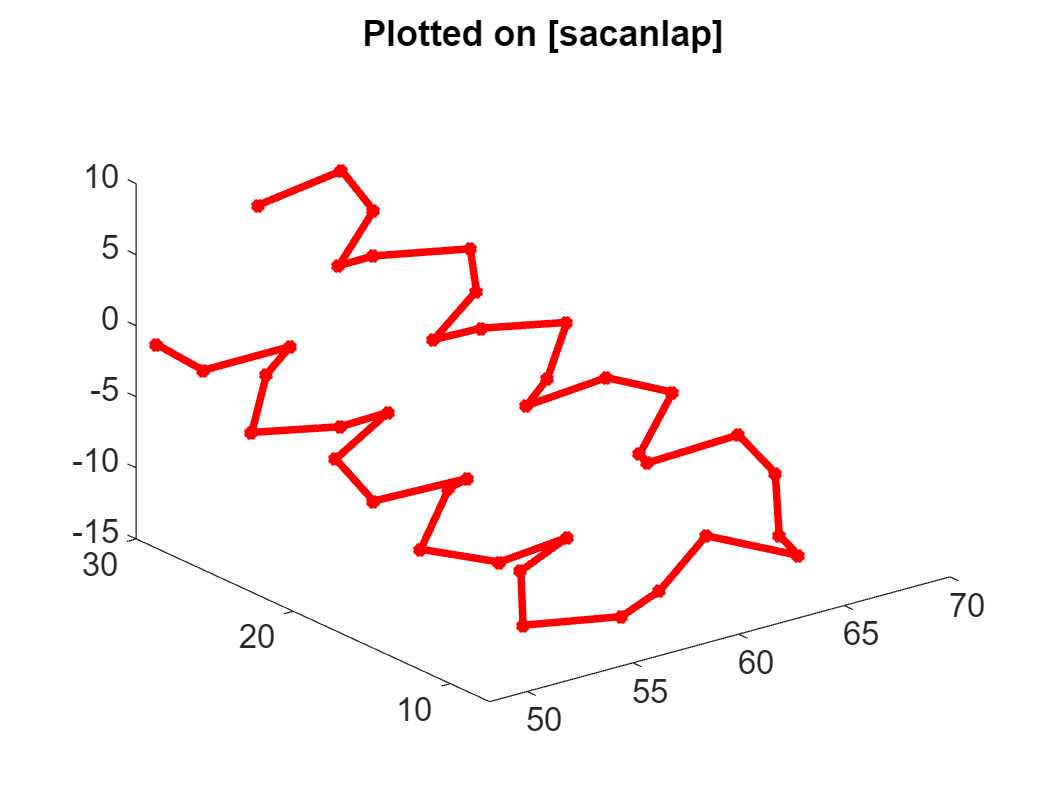

% add folder containing rnafoldga_demo files, so we can reuse those functions:
if isempty(which('bmes'))
	error('You need to add the bmes.ahmet/ folder (it should be in your dropbox) for this code to work. You can do that using "Set Path" in Matlab Home menu or using the addpath() function.');
end
addpath( [fileparts(fileparts(which('bmes')))  '/sim/rnafoldga_demo']);
bmes.diskusage;
file = bmes.downloadurl('https://sacan.biomed.drexel.edu/lib/exe/fetch.php?rev=&media=course:sim2:moleculardynamics:hwptnfoldga:1gzmA48-86.tab','1gzmA48-86.tab');
ptn = readtable(file,'filetype','text');
seq = ptn{:,'base'}; seq=[seq{:}];
locs = ptn{:,{'x','y','z'}};
distmat = squareform(pdist(locs));

rna_plot(locs);

### Detect Hydrogen Bonds

Write a function **ptn_gethydrogenbondedpairs()** to get the hydrogen bonded pairs of amino acids. Your function should return a 2-column matrix of the indices of the residues that have hydrogen bonds between them. The H-donor should be listed in the first column and the H-acceptor in the second column. **Do not sort the pairs matrix, so that the pairs appear in the order of their distances.**

Hydrogen bonds should be determined using the following rules (these rules may not reflect the statistics or constraints of real proteins):

- Amino acids (aka "residues") that are between 3-15 Angstroms are considered hydrogen-bonded (assuming they satisfy additional rules below).

- There needs to be at least 1 residue between hydrogen-bonding (i.e,. amino acids that are consecutive in the sequence cannot form a hydrogen bond.

- Each residue can form H-bond with at most two other different residues. (In reality, these assumptions are not accurate; an amino acid in reality can form additional H-bonds via their side-chains, which we'll ignore here).

- Each residue can act as a H-donor at most once.

- Each residue can act as a H-acceptor at most once.

- If a residue A acts as a H-donor to a residue B; residue A cannot act as a H-acceptor to the residue B.

- A H-bond is formed between an available H-donor and available H-acceptor.

- Proline cannot act as a H-donor, but can act as an H-acceptor.

- If multiple partners satisfy these requirements, use the pair with the smallest distance as H-bonding partners. If there are multiple pairs with the smallest such distance, use the pair that would come first when sortrows were applied to the list of these pairs.

- Follow a greedy matching strategy to pair up the closest eligible/available partners at each step. Repeat until no eligible pairs remain.

Your function should use the distance matrix if one is given as input or calculate it if it is not given.

pairs = ptn_gethydrogenbondedpairs(seq, locs, distmat);
size(pairs)

ans =     37     2


%pairs(1:20,:)'
pairs'

ans =      8    32    36     9    10    11    27    28    29    33    25     1    31     7    34    35    23    14    30    38    19    12    13    15     3     4    18    20    16     2     5    21    17    37    22    39    26
    33    35    39    12    13     8    24    31    32    30    28     4    29    10    37    38    26    17    27    36    21    15    16    18     1     7    20    22    14     5     3    23    19     9    25    34    11


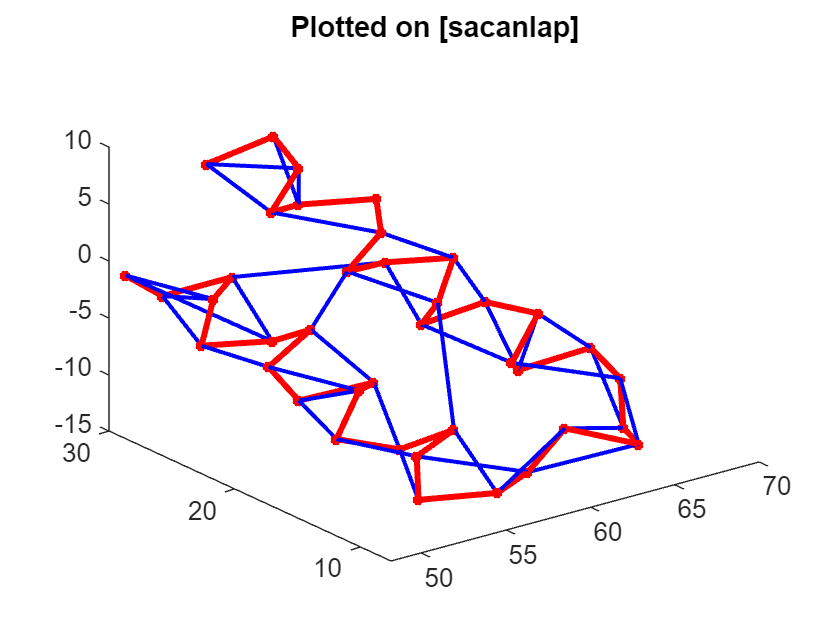

rna_plot(locs,pairs)

### Calculate Fitness

Write a function **ptn_fitness()** that returns a fitness score based on the following criteria. Return the total fitness score as well as information about the breakdown of the fitness scores in the following categories. For violations, the information should contain the number of violations. 

- The more hydrogen bonds a protein has the better the fitness.

- Residues that are consecutive (in the primary sequence) should be between 3.7-3.9 Angstroms apart. For each residue pair that do not satisfy this, use the difference from this ideal distance range as a penalty for fitness. If you penalize for residue pair <i,j>, do not penalize for pair <j,i>. In the information structure, use numseqviolations as the count of these violations and seqviolations as the fitness penalty resulting from them.

- Non-consecutive residues should be further than 3 Angstroms. For each residue pair that do not satisfy this, use the difference from this minimal distance as a penalty for fitness. If you penalize for residue pair <i,j>, do not penalize for pair <j,i>.  In the information structure, use numnonseqviolations as the count of these violations and nonseqviolations as the fitness penalty resulting from them.

Your function should use the distance matrix if one is given as input or calculate it if it is not given. Your function should work with locations formatted as a 3-column matrix as well as given as a row-matrix of concatenated <x,y,z> coordinates.

[fitness,info] = ptn_fitness(seq, locs, distmat)

fitness = 37

info = struct with fields:
            totalhbonds: 37
       numseqviolations: 0
    numnonseqviolations: 0
          seqviolations: 0
       nonseqviolations: 0


## Run Genetic Algorithm to find the best structure

fprintf('Running on [%s]...',bmes.computername)

Running on [sacanlap]...

options = optimoptions('ga','PlotFcn', @gaplotbestf,'UseParallel',true, 'CrossoverFcn',@rnafoldga_crossover);
problem = struct('nvars',numel(seq)*3, 'fitnessfcn', @(v)-ptn_fitness(seq,v),'solver','ga', 'options',options);
galocs = ga(problem);

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


[fitness,info] = ptn_fitness( seq, galocs )

fitness = -92.7266

info = struct with fields:
            totalhbonds: 37
       numseqviolations: 36
    numnonseqviolations: 13
          seqviolations: 121.9018
       nonseqviolations: 7.8248


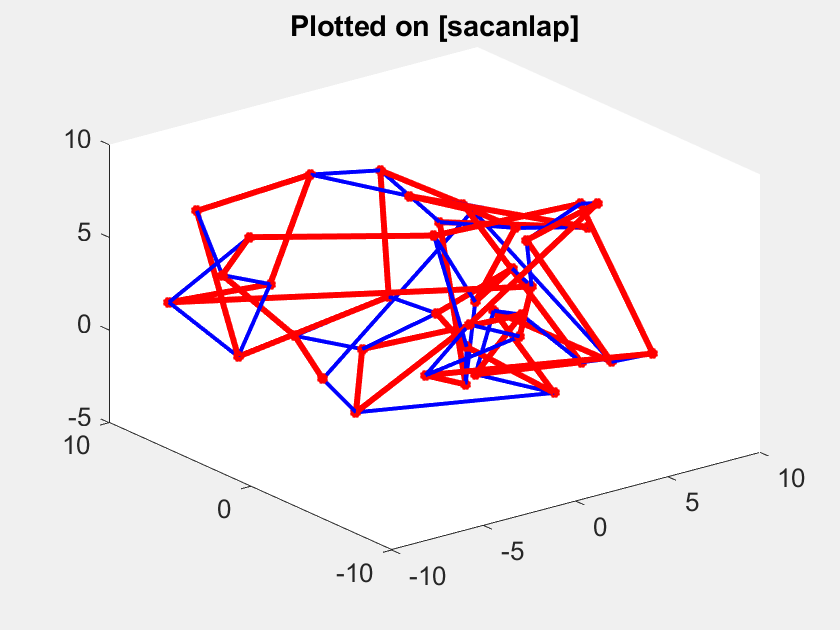

gapairs = ptn_gethydrogenbondedpairs(seq, galocs);
rna_plot(galocs,gapairs)